## **Adding compensation for radial distortion**

Load the data and estimate all the parameters (intrinsic and extrinsics), getting a first estimate of** projection matrix **P.

This estimate will be adjusted later on.

% load checkerboard images
clear imageData
folder = 'images';
imageData = load_data(folder);
% compute camera intrinsic and extrinsic parameters for each image
clear data
data = estimating_extrinsics(imageData); 
n = length(data); % number of images

We can see that by performing projection using the obtain projection matrix, we get a significant error.

Let's see it clearly on the first image. We measure the reprojection error as the distance between the estimated and the measured projections.

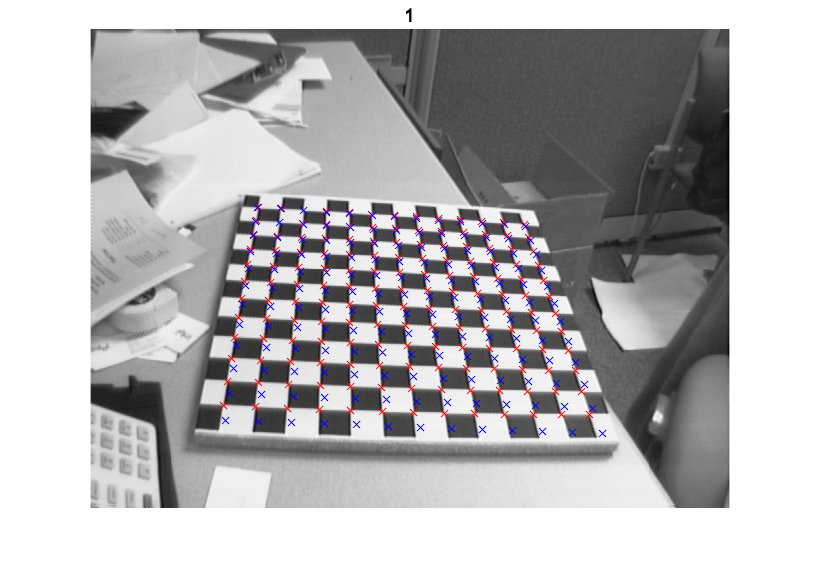

idx = 1; % choose first image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0;

figure
imshow(data(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xpixel=XYpixel(i,1); % u
    Ypixel=XYpixel(i,2); % v
    Xmm=XYmm(i,1);  % x
    Ymm=XYmm(i,2); % y

    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;

    estimated_u =  (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + sqrt(eu^2 + ev^2);

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

fprintf("Obtained reprojection error is: %d pixels", error);

Obtained reprojection error is: 1.200865e+03 pixels

Compute the reprojection error for each image and save it in data structure.

for i=1:n
    error = 0;
    XYpixel = data(i).XYpixel;
    XYmm = data(i).XYmm;

    for j=1:length(XYpixel)
        % coordinates of point in mm
        Xpixel=XYpixel(j,1); % u
        Ypixel=XYpixel(j,2); % v
        Xmm=XYmm(j,1);  % x
        Ymm=XYmm(j,2); % y
    
        m = [Xmm; Ymm; 0; 1];
                
        P = data(i).P;
    
        estimated_u =  (P(1,:)*m)/(P(3,:)*m);
        estimated_v = (P(2,:)*m)/(P(3,:)*m);
        eu = estimated_u - Xpixel; % error on u
        ev = estimated_v - Ypixel; % error on v
    
        error = error + sqrt(eu^2 + ev^2);
    end
    data(i).error = error;
end

Now we apply the procedure for radial distortion compensation in order to obtain a new estimation of P for each image and, most importantly, the radial distortion parameters $k1$ and $k2$, which are needed for the representation of undistorted image.

[new_data, k] = radial_distortion_compensation(data);

iteration 0
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -4.728649e-02  k2 -6.434632e-02
iteration 1
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -3.564140e-02  k2 -3.524960e-02
iteration 2
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -2.819316e-02  k2 -1.195239e-02
iteration 3
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -2.313897e-02  k2 4.379436e-03
iteration 4
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -1.948495e-02  k2 1.459606e-02
iteration 5
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -1.669111e-02  k2 2.022278e-02
iteration 6
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -1.446027e-02  k2 2.272422e-02
iteration 7
lsqr converged at iteration 2 to a solution with relative residual 0.99.
k1 -1.262290e-02  k2 2.324574e-02
iteration 8
lsqr converged at iteration 2 to 

k1 = k(1); k2 = k(2);


Now we have a new estimation of P for each image and we can compute the undistorted projection of our points.

Of course to see what is happening we also have to plot the undistorted representation of our image.

%k1 = -0.253; k2 = 0.124;

idx = 1;
img = data(idx).I;

K = new_data(idx).K;
u0 = K(1,3);
v0 = K(2,3);
alpha_u = K(1,1);
theta = acot(K(1,2)/alpha_u); % skew angle between u and v axes, the angle is measured in radians
alpha_v = K(2,2);%*sin(theta);

for u=1:size(I,1)
    for v=1:size(I,2)
        % find the distorted corresponding coordinates of (u,v)
        rd = ((u-u0)/alpha_u)^2 + ((v-v0)/alpha_v)^2;
        uhat = (u - u0)*(1+ k1*rd + k2*rd^2) + u0;
        vhat = (v - v0)*(1+ k1*rd + k2*rd^2) + v0;
        %fprintf("%d,%d\n",uhat, vhat);
        %fprintf("%d,%d\n",u, v);
        % image undistortion algorithm can produce noninteger values of (u,v)
        % for this reason interpolation is needed
        % find the four neighboring pixels and the distance from the
        % top-left one wrt to u and v axes
        p1 = [floor(uhat); floor(vhat)]; % top left pixel
        p2 = [ceil(uhat); floor(vhat)]; % top right pixel
        p3 = [floor(uhat); ceil(vhat)]; % bottom left pixel
        p4 = [ceil(uhat); ceil(vhat)]; % bottom right pixel
        
        delta_u = (uhat - p1(1));
        delta_v = (vhat - p1(2));
        out_pixel = p1*(1 - delta_u)*(1-delta_v) + p2*delta_u*(1-delta_v) + p3*(1-delta_u)*delta_v + p4*delta_u*delta_v;
      
        % the intensity of I(u,v) in the undistorted image is the one of
        % (uhat, vhat) in the distorted image
        img(u, v) = data(idx).I(round(out_pixel(1)),round(out_pixel(2)));
    end
end

Use these points to construct a system given by the following equations:


$$\hat{u} - u = (u-u_0) r_d^2 k_1 + (u - u_0) r_d^4 k_2$$



$$\hat{v} - v = (v-v_0) r_d^2 k_1 + (v - v_0) r_d^4 k_2$$


same for v, where $(\hat{u}, \hat{v})$  is the expected projected point, while $(u,v)$ is the one that would be obtained through undistorted projection.

% for each image (u0, v0) are the coordinates in pixel of first point
A = zeros(2*npoints, 2); % matrix A has two equations for each point of each matrix
b = zeros(2*npoints, 1);
K = data(1).K; % matrix K of intrinsic parameters
alpha_u = K(1,1);

theta = acot(K(1,2)/alpha_u); % skew angle between u and v axes, the angle is measured in radians
alpha_v = K(2,2)*sin(theta);

u0 = K(1,3);
v0 = K(2,3);

for i=3:3
    for j=1:npoints

        uhat = data(i).XYpixel(j,1);
        u = data(i).expected(j,1);

        vhat = data(i).XYpixel(j,2);
        v = data(i).expected(j,2);

        rd = ((u-u0)/alpha_u)^2 + ((v-v0)/alpha_v)^2;
        
        idx = (i-1)*2*npoints +j*2-1;
        %fprintf("%d\n", idx)
        %idx = j*2 - 1;
        A(idx,1) = (u - u0)*rd;
        A(idx,2) = (u - u0)*rd^2;
        A(idx+1, 1) = (v - v0)*rd^2;
        A(idx+1, 2) = (v - v0)*rd^4;
        b(idx) = uhat - u;
        b(idx+1) = vhat - v;
    end
    
end
k = lsqr(A,b); % same as: inv((A'*A))*A'*b

lsqr converged at iteration 2 to a solution with relative residual 1.


k1 = k(1);
k2 = k(2);
k1

k1 = 0.1192

k2

k2 = -1.1289

inv((A'*A))*A'*b

ans =     0.1192
   -1.1289


k1 = -0.2531;
k2 = 0.1240;

We have that $\hat{x} = x(1 + k_1(x^2+y^2) +k_2(x^4+2x^2y^2+y^4)$ and we want to find $x$

% new system in which the unknowns are x,y
for i=1:n
    for j=1:length(data(i).XYpixel)

        % find the new x,y for each of selected points using newton method
        uhat = data(i).XYpixel(j,1);
        vhat = data(i).XYpixel(j,2);
        xhat = (uhat - u0)/alpha_u; 
        yhat = (vhat - v0)/alpha_v; 
        %fprintf("%d %d\n", xhat,yhat);
        
        f1 = @(x,y) x*(1 + k1*(x^2 + y^2) + k2*(x^4 +2*x^2*y^2 + y^4)) - xhat;
        f2 = @(x,y) y*(1 + k1*(x^2 + y^2) + k2*(x^4 +2*x^2*y^2 + y^4)) - yhat;
        J = @(x,y) [1+ 3*k1*x^2 + k1*y^2 + 5*k2*x^4 + 6*k2*x^2*y^2 + k2*y^4, ...
                    2*k1*x*y + 4*k2*x^3*y + 4*k2*x*y^3; ...
                    2*k1*x*y + 4*k2*x*y^3 + 4*k2*x^3*y, ...
                    1+ 3*k1*y^2 + k1*x^2 + 5*k2*y^4 + 6*k2*x^2*y^2 + k2*x^4];
        
        x0 = [0; 0]; % starting point for newton's method
        res = newtonMethod(f1,f2, J, x0, 10^(-8), 100);
        
        x = res(1); y = res(2);
        % update m' (pixel values of each point) using the obtained result
        % (values of x,y)
        data(i).XYpixel(j,1) = alpha_u*x + u0; %update u
        data(i).XYpixel(j,2) = alpha_v*y + v0; %update v
        %fprintf("%d %d\n", x,y);
    end
end

data = estimating_extrinsics(data); 
 

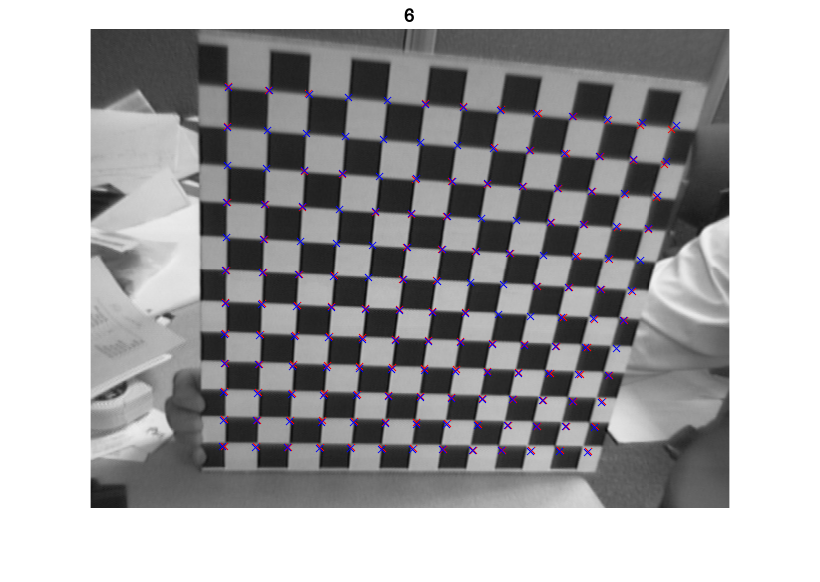

data = new_data;
idx = 6; % choose first image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0;


figure
imshow(J1, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xpixel=XYpixel(i,1); % u
    Ypixel=XYpixel(i,2); % v
    Xmm=XYmm(i,1);  % x
    Ymm=XYmm(i,2); % y

    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;

    estimated_u =  (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + eu^2 + ev^2;

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

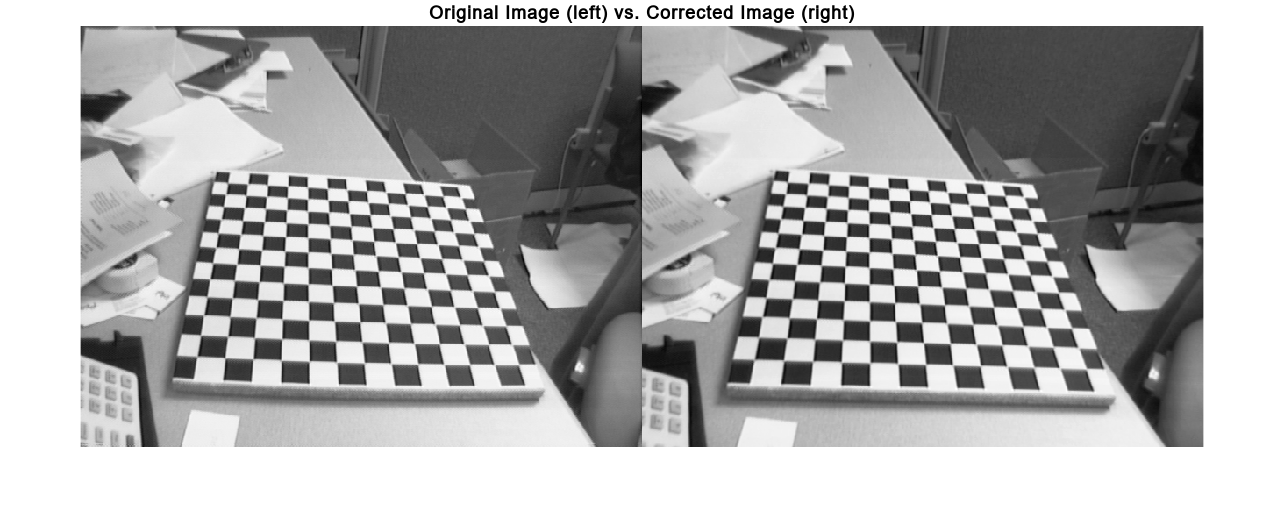

images = imageDatastore(fullfile('images'), "FileExtensions",[".jpg",".tif"]);
[imagePoints,boardSize] = detectCheckerboardPoints(images.Files,'PartialDetections', false);

squareSize = 30;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

idx = 1;
I = readimage(images,idx); 
imageSize = [size(I,1),size(I,2)];
cameraParams = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);

I = images.readimage(idx);
J1 = undistortImage(I,cameraParams);
figure; imshowpair(I,J1,'montage');
title('Original Image (left) vs. Corrected Image (right)');